# WP3

Nota: prima di eseguire il codice assicurarsi di aver impostato come working directory di MATLAB la cartella "WP3".

## Parametri del modello

clear all  clc;
p1 = 0.0151; %tasso base di rimozione del glucosio dal sangue
p2 = 0.0313; %tasso rimozione del glucosio dovuto all'insulina
p3 = 0.0097;
ge = 0.97;
ie = 0.003;
u_eq=1.003;

I parametri nella sezione successiva sono il risultato dei work package precedenti.

x_eq = [0.0451; 0.3099];
x1_eq = x_eq(1);
x2_eq = x_eq(2);
% Il K è il guadagno del controllore LQI progettato nel WP2
K = [-1272.43538878761    165.594962781475    408.248290463863];
A = [-p1-x_eq(2) -x_eq(1); 0 -p2];
B = [0; p3];
C = [1 0];
D = [0];

## Progettazione dell'osservatore

Il primo passo nella progettazione dell'osservatore è trovare la matrice di osservabilità e controllare se il sistema è osservabile.

W0 = [C;C*A];
rank(W0)

ans = 2

La matrice di osservabilità ha rango pieno, dunque il sistema è osservabile.

A questo punto si procede con il calcolo di L, imponendo le prestazioni dinamiche dell'osservatore.

% matrice di osservabilità in forma canonica
syms x
polyA = charpoly(A, x);
polyA = coeffs(polyA);
a1 = polyA(2);
a2 = polyA(1);
W0_tilde = inv([1,0;a1,1]); %in alternativa W0_tilde = [1 0;-a1 1];

% calcolo dei coefficienti del polinomio desiderato
Sett_time = 2.2;
zeta = 1;
w0 = 5.8/Sett_time;
pd1 = 2*zeta*w0

pd1 = 5.2727

pd2 = w0^2

pd2 = 6.9504


L = inv(W0)*W0_tilde*[pd1-a1;pd2-a2];
L = eval(L);

È possibile controllare che i coefficienti del polinomio caratteristico dell'osservatore siano quelli desiderati.

syms x
polyObs = charpoly(A-L*C,x);
coeffs_obs = eval(coeffs(polyObs))

coeffs_obs =     6.9504    5.2727    1.0000


Simulazione del sistema LQI con l'osservatore:

simout = sim('v1_lqi_observer.slx');

Valutazione delle performance dinamiche. Con $\hat{x}$ (nel codice x_hat) si indica la stima dello stato.

t = simout.t;
t = t.Time;
y = simout.y;
u = simout.u;
x = simout.x;
x_hat = simout.x_hat.Data;

x_hat_1_stepinfo = stepinfo(x_hat(:,1),t,x1_eq)

x_hat_1_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 14.2636
     SettlingTime: 14.8272
      SettlingMin: 0.0451
      SettlingMax: 0.0977
        Overshoot: 116.5747
       Undershoot: 0
             Peak: 0.0977
         PeakTime: 0.4754


x_hat_2_stepinfo = stepinfo(x_hat(:,2),t,x2_eq)

x_hat_2_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 7.4072
     SettlingTime: 10.2339
      SettlingMin: -0.6156
      SettlingMax: 0.6547
        Overshoot: 111.2555
       Undershoot: 198.6582
             Peak: 0.6547
         PeakTime: 1.3060


y_stepinfo = stepinfo(y,t,y(end)) % Settling time = 14s. Overshoot = 124%

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 13.3754
     SettlingTime: 14.0567
      SettlingMin: 0.0453
      SettlingMax: 0.1017
        Overshoot: 124.4396
       Undershoot: 0
             Peak: 0.1017
         PeakTime: 0.1796


u_stepinfo = stepinfo(u,t,u(end)) % Peak = 175

u_stepinfo = struct with fields:
         RiseTime: 5.2419e-04
    TransientTime: 3.0014
     SettlingTime: 15.8094
      SettlingMin: -61.4506
      SettlingMax: 175.7395
        Overshoot: 1.7350e+04
       Undershoot: 6.1017e+03
             Peak: 175.7395
         PeakTime: 0.3135


u_min = min(u) % picco minimo dell'ingresso di controllo

u_min = -61.4506

#### Plot dei grafici

In prima istanza si raffigura l'uscita del sistema a ciclo chiuso in presenza dell'osservatore.

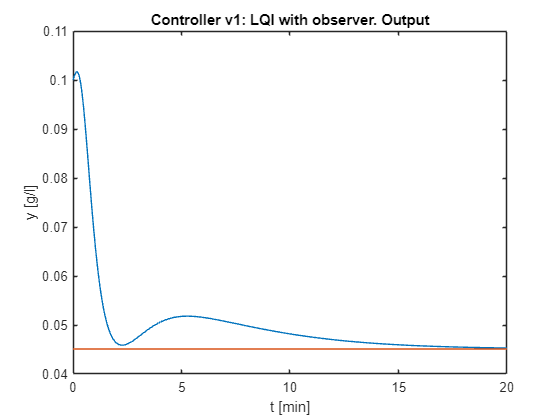

figure
plot(t,y)
title("Controller v1: LQI with observer. Output")
xlabel("t [min]")
ylabel("y [g/l]")
hold on
plot(t,ones(size(t))*0.045102)

In seconda istanza si raffigura l'andamento dell'ingresso di controllo nel tempo.

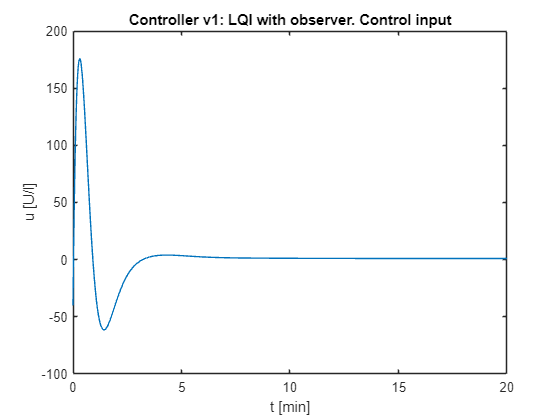

figure
plot(t,u)
title("Controller v1: LQI with observer. Control input")
xlabel("t [min]")
ylabel("u [U/l]")

Infine, si confronta lo stato del sistema con quello stimato.

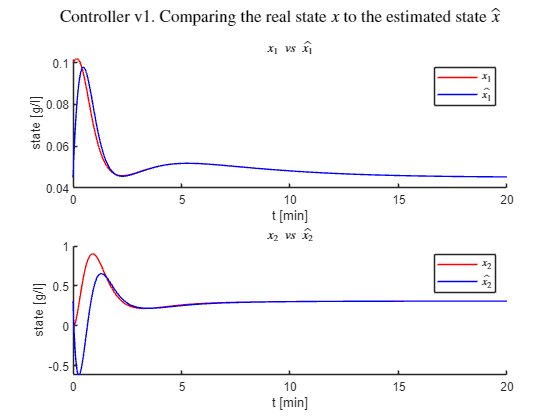

x1 = x(:,1);
x2 = x(:,2);
x1_hat = x_hat(:,1);
x2_hat = x_hat(:,2);
figure;
sgtitle({'Controller v1. Comparing the real state $x$ to the estimated state $\hat{x}$'},'Interpreter','latex');
subplot(2,1,1);
hold on;
title({'$x_1 \ vs \ \hat{x_1}$'},'Interpreter','latex');
plot(t,x1,'r');
plot(t,x1_hat,'b');
legend({'$x_1$';'$\hat{x_1}$'},'Interpreter','latex');
xlabel('t [min]');
ylabel('state [g/l]');

subplot(2,1,2);
hold on;
title({'$x_2 \ vs \ \hat{x_2}$'},'Interpreter','latex');
plot(t,x2,'r');
plot(t,x2_hat,'b');
legend({'$x_2$';'$\hat{x_2}$'},'Interpreter','latex');
xlabel('t [min]');
ylabel('state [g/l]');